# Week10: Redfield ratio in the P18 cruise

(recycled from Week2)

% safety first
close all;
clear all;

% get data as column vectors
data=csvread('33RO20161119_hy1.csv',151,2);
index = ["STNNBR", "CASTNO", "SAMPNO", "BTLNBR", "BTLNBR_FLAG_W", "DATE", "TIME", "LATITUDE", "LONGITUDE", "DEPTH", "CTDPRS", "CTDTMP", "CTDSAL", "CTDSAL_FLAG_W", "SALNTY", "SALNTY_FLAG_W", "CTDOXY", "CTDOXY_FLAG_W", "OXYGEN", "OXYGEN_FLAG_W", "SILCAT", "SILCAT_FLAG_W", "NITRAT", "NITRAT_FLAG_W", "NITRIT", "NITRIT_FLAG_W", "PHSPHT", "PHSPHT_FLAG_W", "CFC11", "CFC11_FLAG_W", "CFC12", "CFC12_FLAG_W", "TCARBN", "TCARBN_FLAG_W", "ALKALI", "ALKALI_FLAG_W", "PH_SWS", "PH_SWS_FLAG_W", "PH_TMP", "POC", "POC_FLAG_W", "PON", "PON_FLAG_W", "SF6", "SF6_FLAG_W"];
for n=1:length(index)
    com=index(n)+'=data(:,n);';
    eval(com);
end

% first calculate absolute salinity
sa=gsw_SA_from_SP(CTDSAL,CTDPRS,LONGITUDE,LATITUDE);
% then calculate conservative temperature
ct=gsw_CT_from_t(sa,CTDTMP,CTDPRS);
% then sigma theta
st=gsw_sigma0(sa,ct);

% Select the desired data
isgood=(NITRAT_FLAG_W==2) & (PHSPHT_FLAG_W==2);
isoxic=OXYGEN>20;
ind=(isgood==true)&(isoxic==true);
% trim the data
x=PHSPHT(ind);
xlab='P';
y=NITRAT(ind);
ylab='N';

% perform linear regression NO3 onto PO4
c=cov(x,y);
a=c(1,2)/c(1,1); % slope
b=mean(y)-a*mean(x); % intercept

% calculate R2 value
r2=c(1,2)^2/c(1,1)/c(2,2);

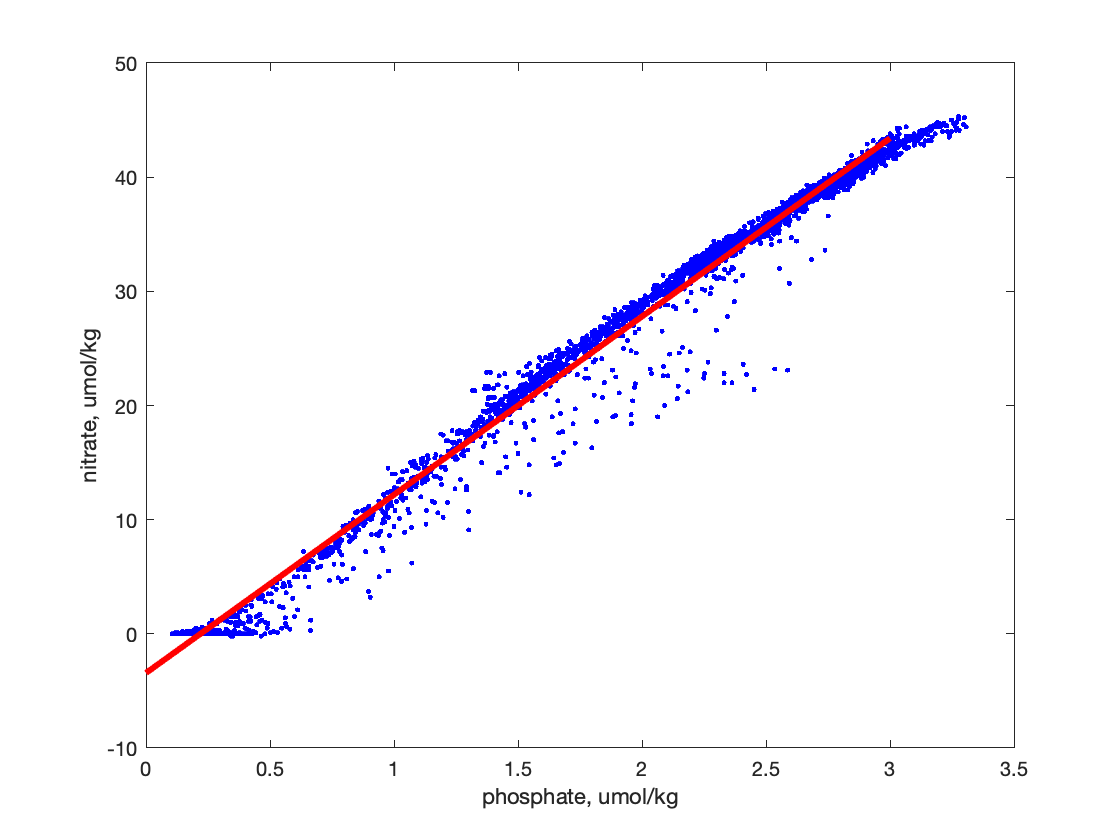

% plotting
% expand the linear regression
x0=linspace(0,3,20);
y0=a*x0+b;

% plot the result
plot(x,y,'b.');
hold on;
plot(x0,y0,'r-','linewidth',3);
xlabel('phosphate, umol/kg')
ylabel('nitrate, umol/kg')

disp(['N:P ratio is ',num2str(a,3),' and R2 value is ',num2str(r2,3)]);

N:P ratio is 15.6 and R2 value is 0.986
